verticesRoof = [-1, 1, 1,-1,-0.5,0.5, 0.5 ,-0.5;
-1,-1, 1, 1,-0.5,-0.5, 0.5, 0.5;
-1,-1,-1,-1, 0.5, 0.5, 0.5, 0.5;
1, 1, 1, 1, 1, 1, 1, 1];
ARoof=[    1,0,0,0;
    0,1,0,0;
    0,0,0.4,0;
    0, 0,0, 1];
verticesRoof = ARoof * verticesRoof;
verticesRoof = verticesRoof + [0;-0.5;1.2;0];
verticesRoof = verticesRoof + [0;0;-0.4;0]; % Башня
verticesGUN = [
-1, 1, 1,-1,-1, 1, 1 ,-1;
-1,-1, 1, 1,-1,-1, 1, 1;
-1,-1,-1,-1, 1, 1, 1, 1;
1, 1, 1, 1, 1, 1, 1, 1];
AGUN=[
    0.2,0,0,0;
    0,1.2,0,0;
    0,0,0.2,0;
    0, 0,0, 1];
verticesGUN = AGUN * verticesGUN;
verticesGUN = verticesGUN + [0;-2;0.65;0]; %  Ствол
verticesTANK = [
-1, 1, 1,-1,-1, 1, 1 ,-1;
-1,-1, 1, 1,-1,-1, 1, 1;
-1,-1,-1,-1, 1, 1, 1, 1;
1, 1, 1, 1, 1, 1, 1, 1];
ATANK=[1,0,0,0;
    0,2,0,0;
    0,0,0.4,0;
    0,0,0,1];
verticesTANK = ATANK * verticesTANK; % Корпус
verticesG = [
-0.9, 0.9, 0.9,-0.9,-1, 1, 1 ,-1;
-0.9,-0.9, 0.9, 0.9,-1,-1, 1, 1;
-0.9,-0.9,-0.9,-0.9, 1, 1, 1, 1;
1, 1, 1, 1, 1, 1, 1, 1];
AG=[0.3,0,0,0;
    0,2.4,0,0;
    0,0,0.45,0;
    0,0,0,1];
verticesG = AG * verticesG;
verticesGL = verticesG + [1.25;0;-0.5;0];
verticesGR = verticesGL + [-2.5;0;0;0]; % если что, выше задаются гусеницы, но не Вупсень и Пупсень
facesHouse = [1, 2, 6, 5;
2, 3, 7, 6;
3, 4, 8, 7;
4, 1, 5, 8;
1, 2, 3, 4;
5, 6, 7, 8];% House - то сначала думал сделать дом
TANK = horzcat(verticesTANK, verticesRoof, verticesGUN, verticesGL, verticesGR); % Хочу танк одной матрицей
faces = horzcat(facesHouse', 8+facesHouse', 16+facesHouse',24+facesHouse',32+facesHouse')' % для этого плоскости тоже описываются одной

faces =      1     2     6     5
     2     3     7     6
     3     4     8     7
     4     1     5     8
     1     2     3     4
     5     6     7     8
     9    10    14    13
    10    11    15    14
    11    12    16    15
    12     9    13    16


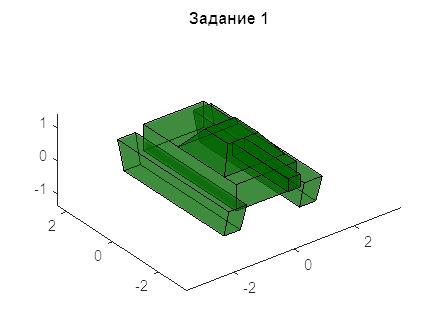

reed=[0,0.4,0,0.5];
reod=[0.2,0.2,0.2,0.5];
rgba = [1,0.5,0, 0.5];
title('Задание 1');
% Dshow ( verticesRoof0, facesHouse ,reed ) % вызвали отрисовку
Dshow ( TANK , faces ,reed )

% Dshow ( verticesGL , facesHouse ,reod )
% Dshow ( verticesGR , facesHouse ,reod )
% Dshow ( verticesGUN , facesHouse ,reed )
% Dshow ( verticesTANK , facesHouse ,reed )
% Dshow ( verticesRoof , facesHouse ,reed )

function DrawShape ( vertices , faces , color ) % принял набор координат вершин, 
% комбинации крайних точек граней, цвет
patch ("Vertices", ( vertices (1:3 ,:) ./ vertices (4 ,:))', "Faces", faces , ...
    "FaceAlpha", color(4), "FaceColor", color(1:3));
% разделили первые три координаты вершины на 4-ю за счёт ./ поэлементно
% это было на тот случай, если мы захотим рисовать под углом
% patch создало поверхность на этих вершинах,
% используя то описание граней и цвет
end

function Dshow ( verticesCube , facesCube , rgba )
DrawShape ( verticesCube , facesCube , rgba ) % вызвали отрисовку
axis equal; % чтобы была ДПСК
view (3); % смотрим в 3D
end